# `Clear Section`

clear           
clc
close all

# `Generate Ensample`

A=4;                                        % Amplitude Value
number_of_enamples=500;
number_of_bits=100;
number_of_samples_per_bit=7;
number_of_samples=number_of_bits*number_of_samples_per_bit;
Total_Transmitted_Data=zeros(number_of_enamples, number_of_samples-1);
for i = 1 : number_of_enamples
    if i == 1
        Total_Transmitted_Data = Generate_Random_Data();
else
    Total_Transmitted_Data = [Total_Transmitted_Data; Generate_Random_Data()];
    end
end

# `Calculate Statistical Mean`

# `Calculate Statistical AutoCorrelation function`

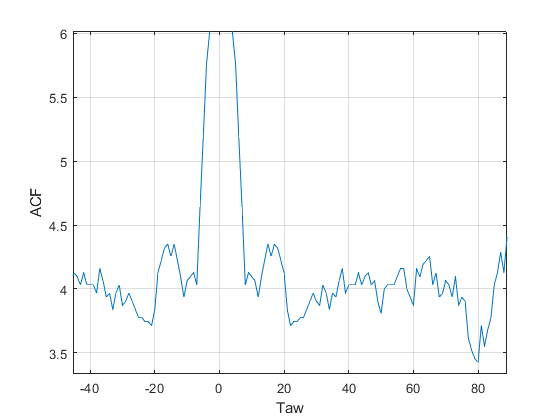

result=0;
average=zeros(1, number_of_samples);   
for i = 1 : number_of_samples
    for j = 1 : number_of_enamples  
        realization=Total_Transmitted_Data(j,:);
        result= result + realization(1)*realization(i);
    end
    average(i)=result/number_of_enamples;
    result=0;
end
average=[fliplr(average) average];
plot((-(number_of_samples-1):number_of_samples), average)
grid on
xlabel("Taw")
ylabel("ACF")
%xlim([-56 56])
ylim([-A^2+5 A^2+5])

# `Calculate Time Average Mean`

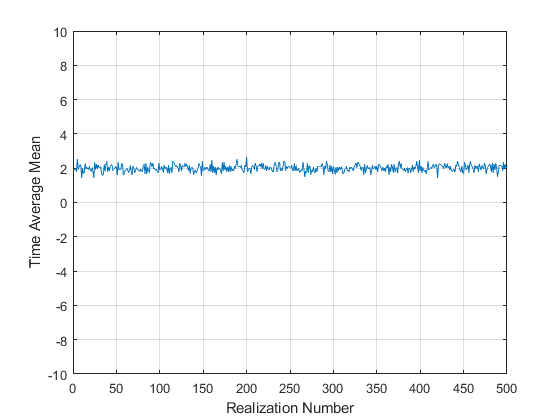

Time_Mean = zeros(1, number_of_enamples);
realization_number=1;  % change it from 1 to number_of_enamples
for i = 1 : number_of_enamples
    Time_Mean(realization_number,i) = sum(Total_Transmitted_Data(i,:)/length(Total_Transmitted_Data(i,:))); 
end
plot(Time_Mean)
grid on
xlabel("Realization Number")
ylabel("Time Average Mean")
ylim([-10 10])

# `Calculate Time Average Autocorrelation`

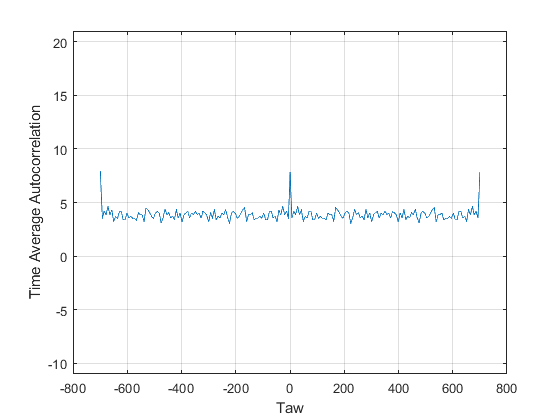

x1=Total_Transmitted_Data(1, :);
Auto_Corr= zeros(1, number_of_samples);
result=0;
for i = 1 : number_of_samples
    if i == 1
        x2 = x1;
    else
        x2=[x1(i+1: number_of_samples), x1(1:i)];
    end
    result =x1.*x2;
    Auto_Corr(i)=sum(result)/length(result);
end
Auto_Corr=[fliplr(Auto_Corr) Auto_Corr];
plot((-(number_of_samples-1):number_of_samples), Auto_Corr)
%plot([0:number_of_samples-1],Auto_Corr)
grid on
xlabel("Taw")
ylabel("Time Average Autocorrelation")
%xlim([-50 50])
ylim([-A^2+5 A^2+5])

# `Generate Random Data`

function data_transmitted = Generate_Random_Data()
A=4;                                        % Amplitude Value
number_of_bits=100;                         % number of bits in each realization
number_of_samples=7;                        % number of samples for each bit
data=randi(2,[1,number_of_bits+1])-1;       % generate 1x100 random numbers '0' or '1' 
%%%%%%%% change this line according to line coding %%%%%%%%
%data=(2*data-1)*A;                         % mapping to A & -A (Polar NRZ)
data=data*A;                                % mapping to A & 0  (Unipolar NRZ)
                                            % mapping           (Polar RZ)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
data=repmat(data, number_of_samples, 1);    % repeat each bit 7 times to sample DAC every 10ms
data=data(:);                               % convert data to column vector 700x1

### `Generate random time shift`

td=randi(number_of_samples)-1;              % generate random number from 0 to 6

### `Concatenate with Random Data`

data_transmitted = (data(td+1:700+td))';    % window data from td to 700+td (700 samples)

### `Plot Transmitted data`

% plot(data_transmitted)
% grid on
% ylim([-A-2, A+2])
end